график

plot3(x,y,z)

анимация

comet3(x,y,z)

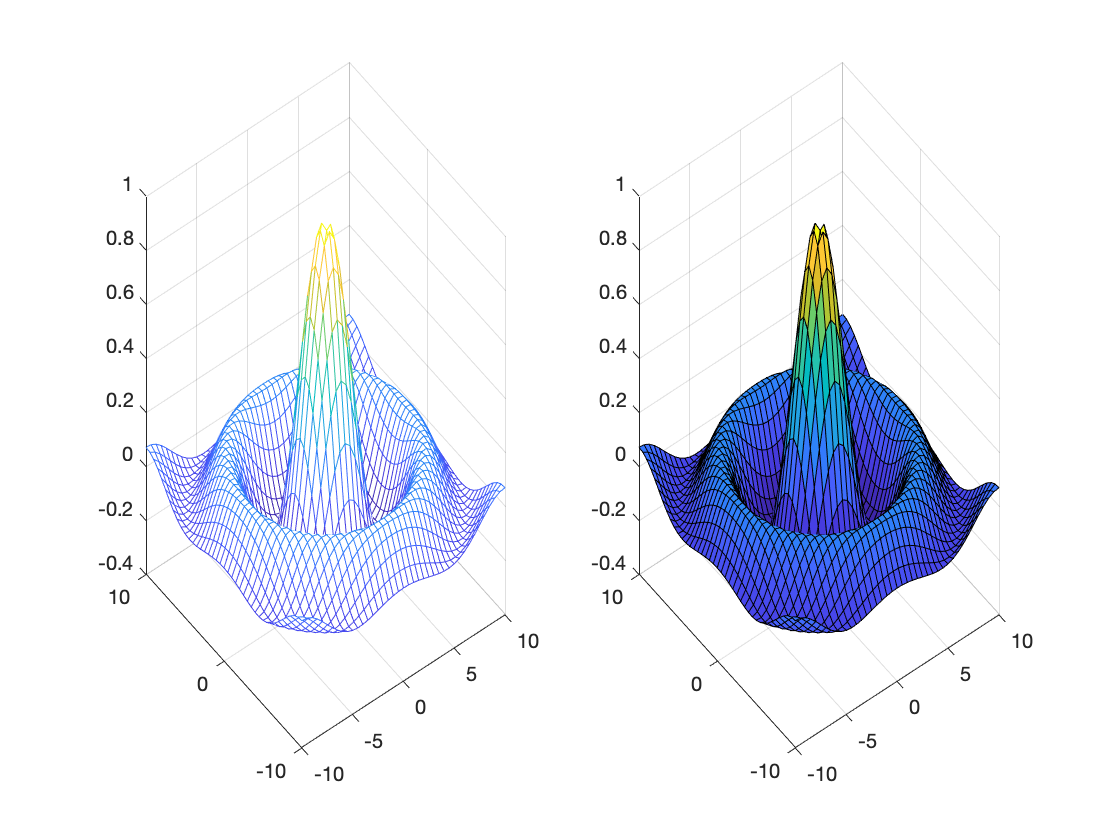

t=0:0.05:8*pi;
x=2*sin(t);
y=3*cos(t);
comet3(x,y,t);

Построение поверхностей

1) формирование сетки meshgrid

[X,Y] = meshgrid(a:h1:b , c:h2:d)

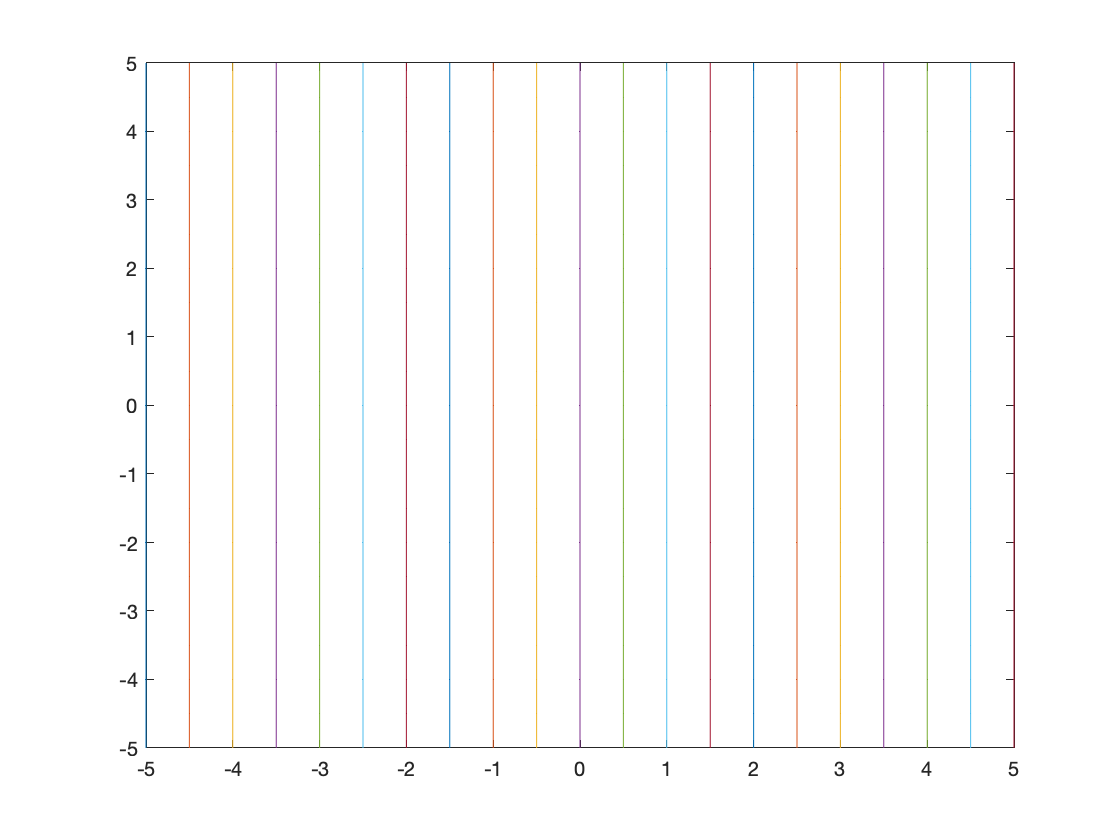

[x,y] = meshgrid(-5:0.5:5, -5:0.5:5);
plot(x,y);

2) построение самой поверхности

mesh(X,Y,Z) - опорная сетчатая поверхность

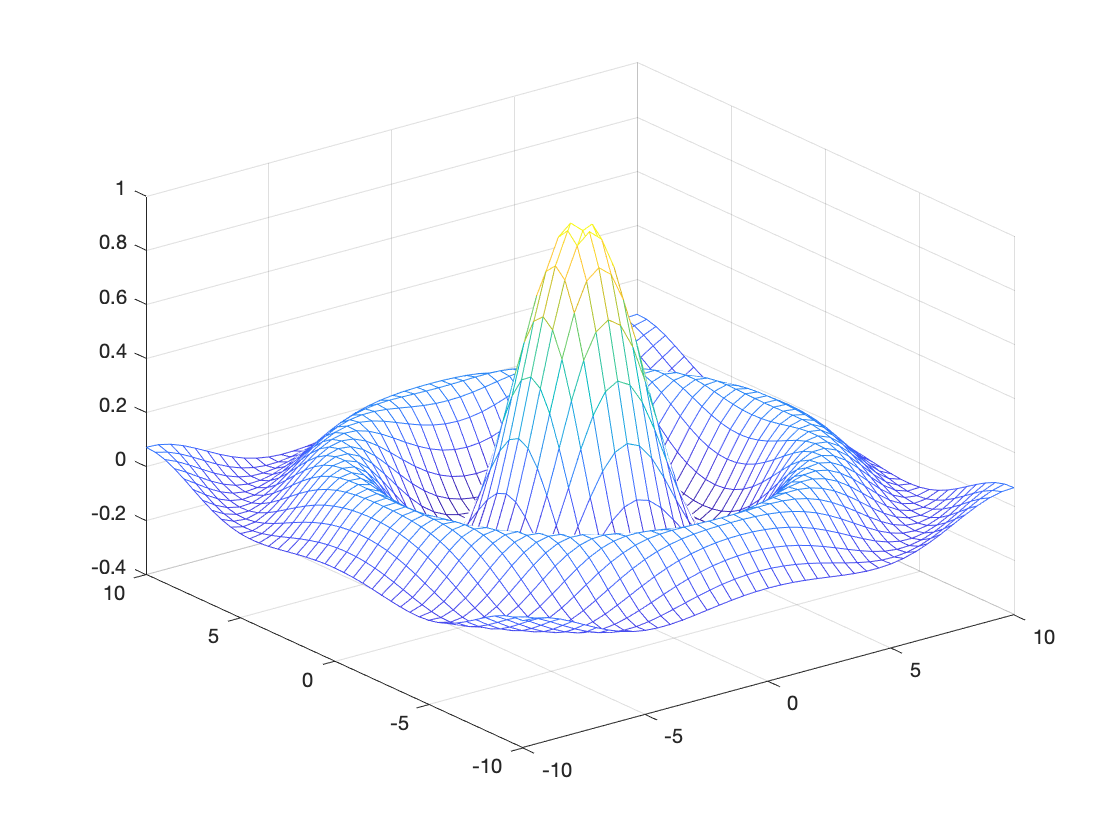

x = -10:0.5:10; y = -10:0.5:10;
[X,Y]= meshgrid(x,y); %сетка узлов
Z = sin(sqrt(X.^2+Y.^2))./sqrt(X.^2+Y.^2);
mesh(X,Y,Z)


colormap('parula');

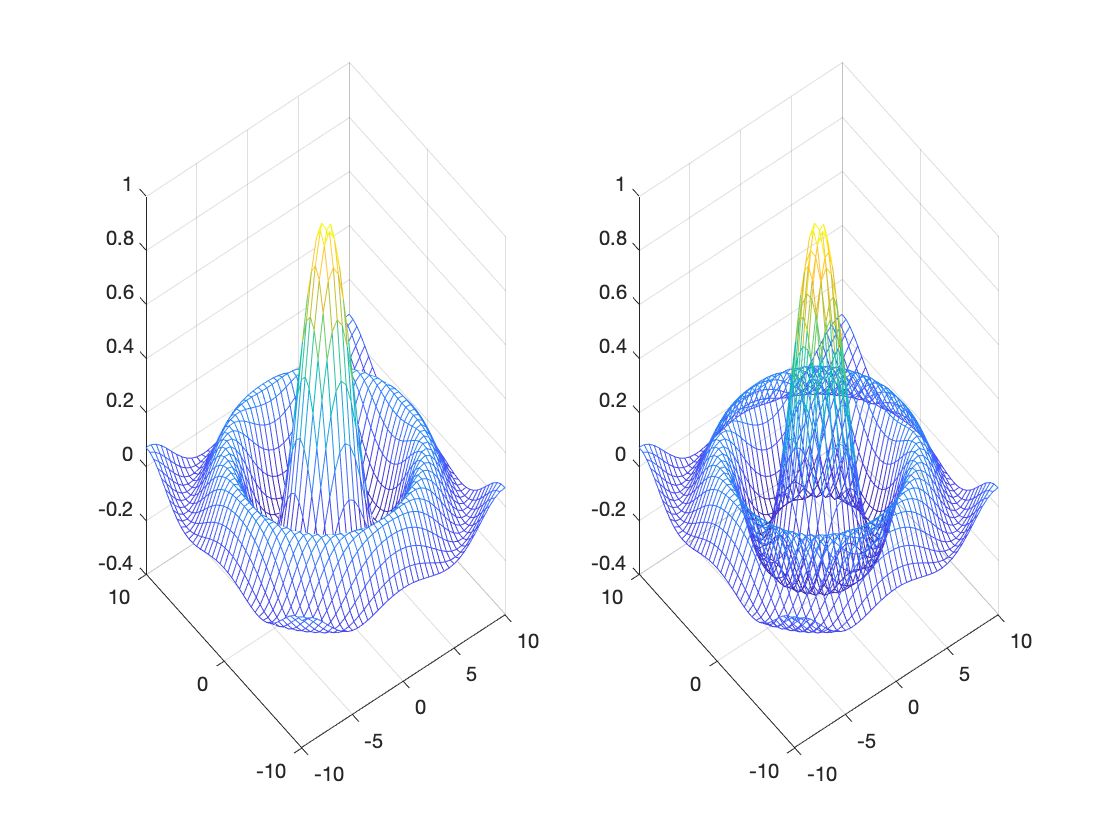

subplot(1,2,1);
mesh(X,Y,Z);
hidden on

subplot(1,2,2);
mesh(X,Y,Z);
hidden off %просвечивающаяся поверхность

Сплошная поверхность

surf, surfc, surfl (X,Y,Z)

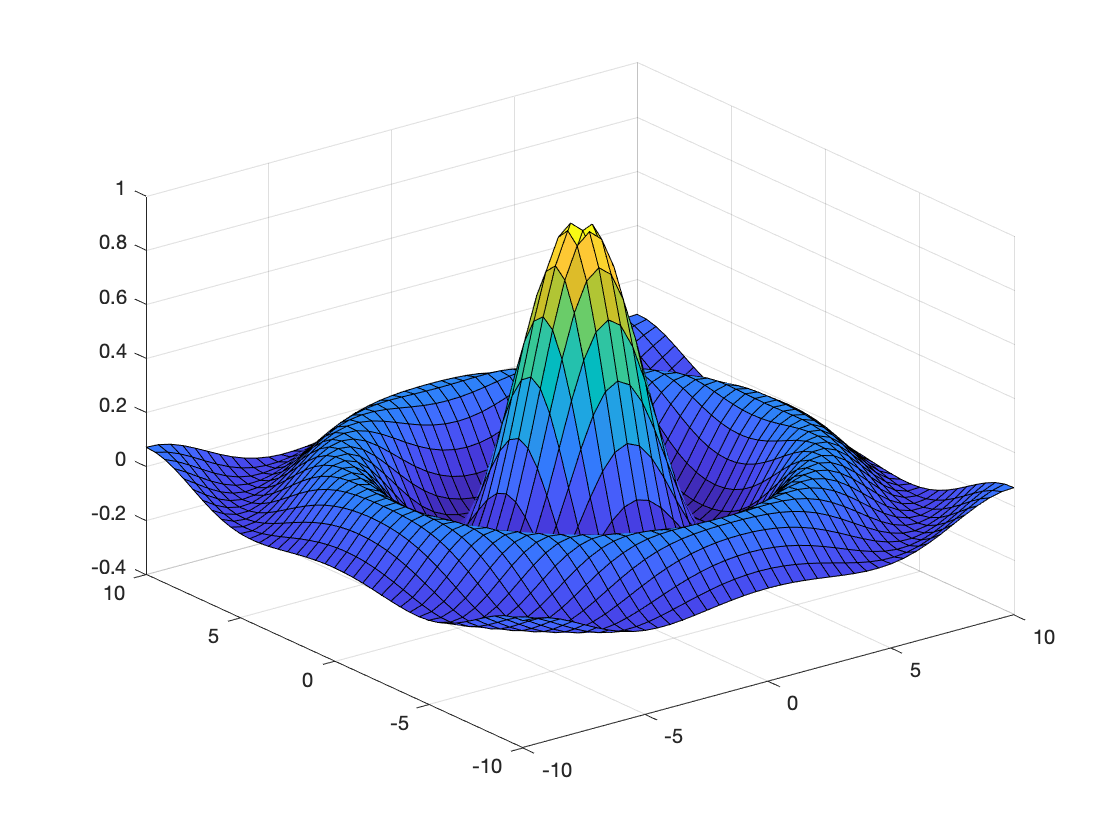

clear all
x = -10:0.5:10; y = -10:0.5:10;
[X,Y]= meshgrid(x,y); %сетка узлов
Z = sin(sqrt(X.^2+Y.^2))./sqrt(X.^2+Y.^2);
figure
surf(X,Y,Z)

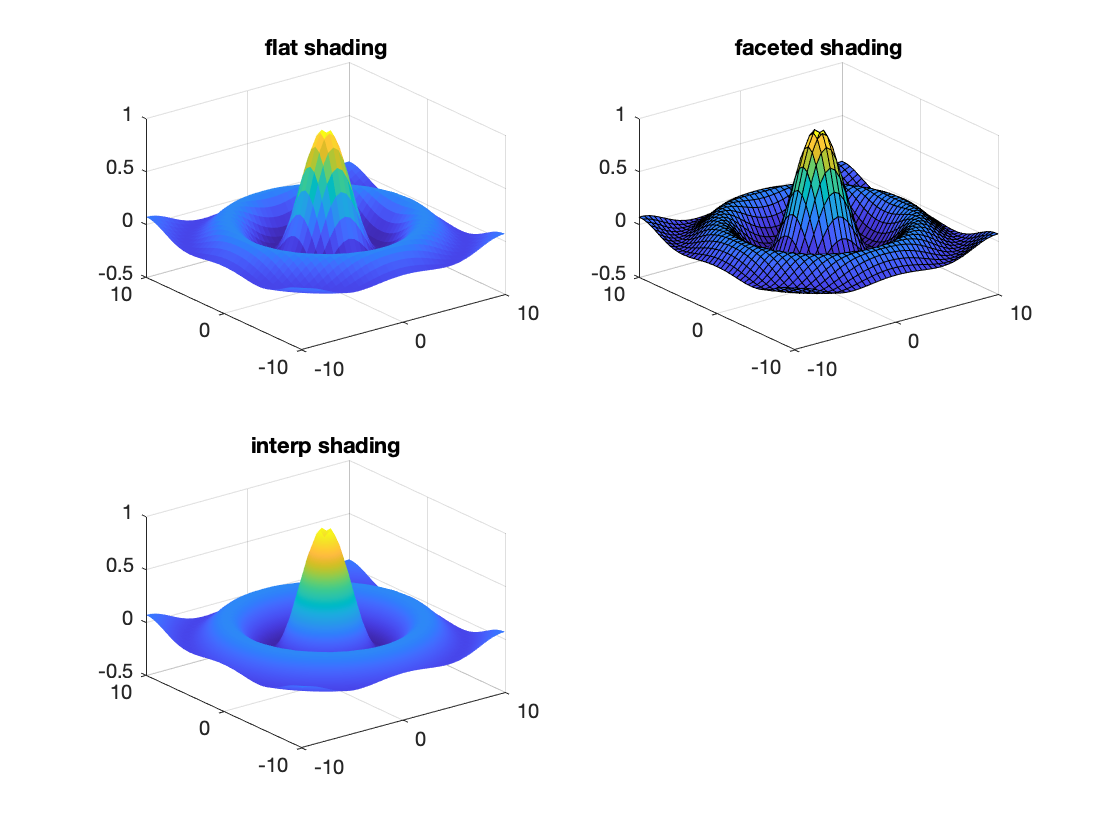


figure
subplot(2,2,1)
surf(X,Y,Z)
shading flat
title('flat shading')

subplot(2,2,2)
surf(X,Y,Z)
shading faceted
title('faceted shading')

subplot(2,2,3)
surf(X,Y,Z)
shading interp
title('interp shading')

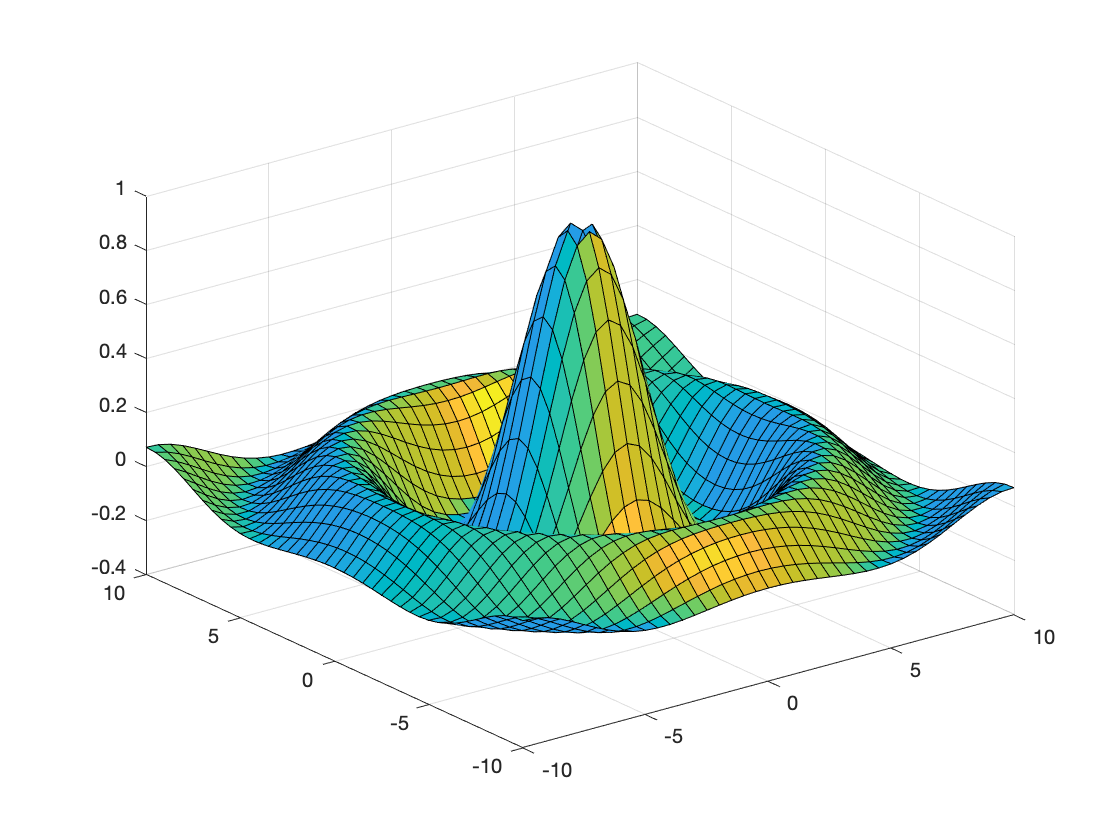


figure
surfc(X,Y,Z)


figure
surfl(X,Y,Z)


ezsurf - если в параметрическом виде

ezsurf(f1(u,v), f2(u,v), f3(u,v), [u_min, u_max, v_min, v_max])

x^2/a^2 + y^2/b^2 = z

можем задать параметризацию

x = r*cos(fi)

y = r*sin(fi)

z=r^2/a^2

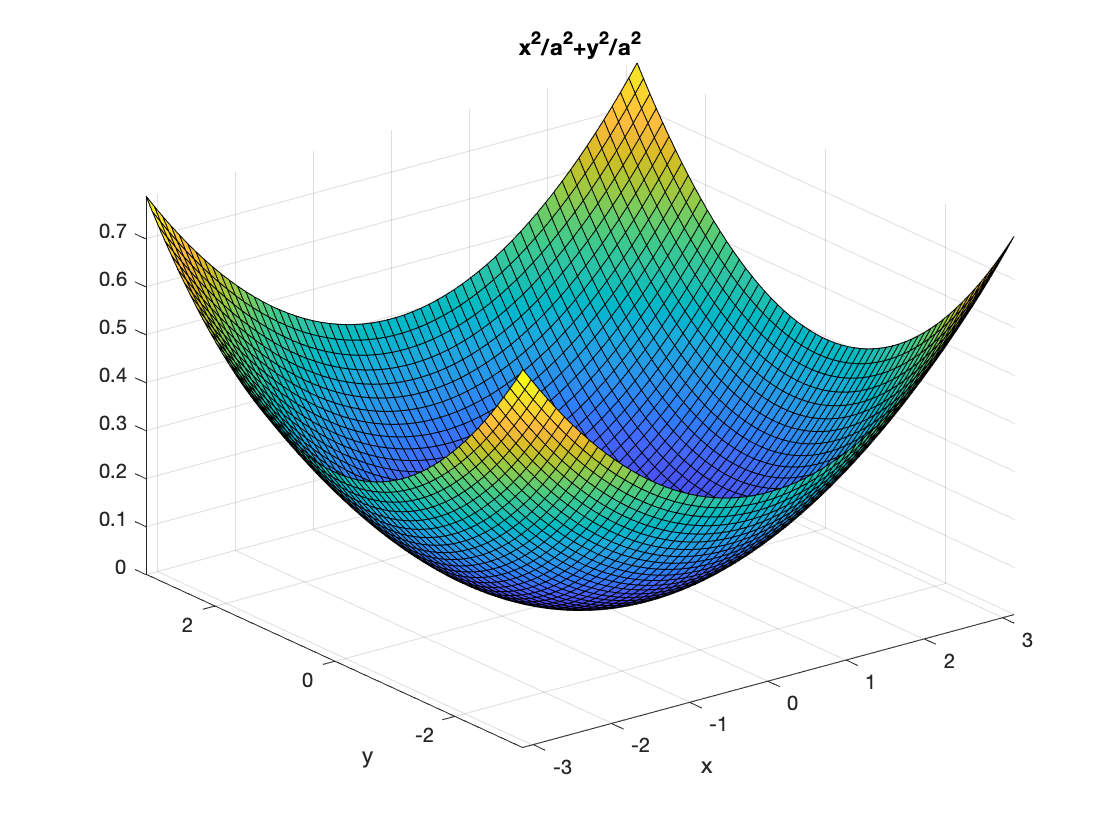

a = 5;
b = 1;
F = @(x,y)x.^2/a^2 + y.^2/a^2; %указатель на функцию F c переменными x,y
ezsurf(F, [-pi,pi,-pi,pi])

a = 6

a = 6

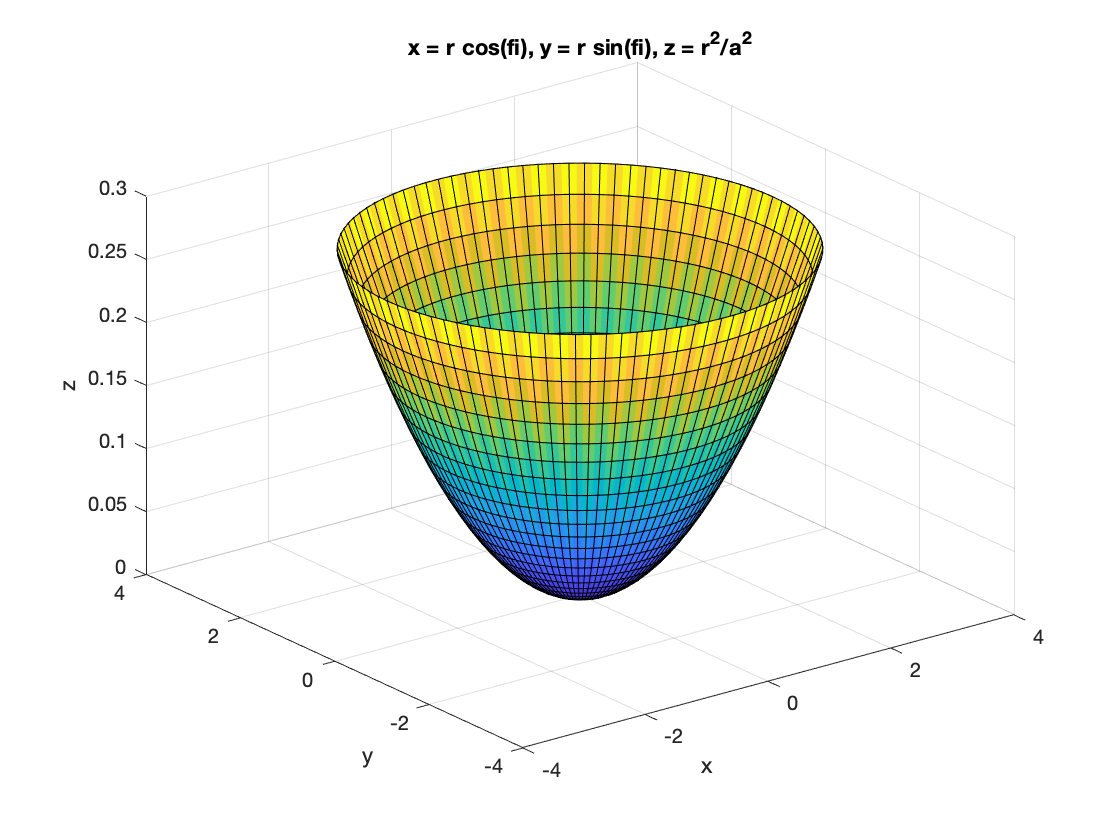

x = @(r,fi) r.*cos(fi);
y = @(r,fi) r.*sin(fi);
z= @(r,fi) r.^2/a^2;
ezsurf(x,y,z, [-pi,pi,-pi,pi])